# Matlab Graph One Variable Function

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

## fplot a Function of X

Given a cubic (polynomial) function, graph it using the fplot function, between some values along the domain of the function. This function is defined everywhere along the real-line. Note that fplot automatically resizes the y-scale to show the full plot clearly.

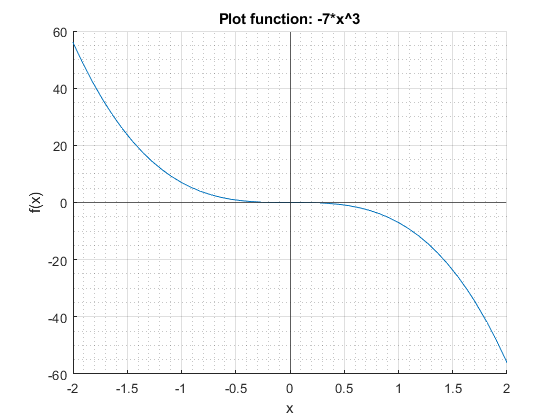

% close all
figure();
hold on;

% Define a function
syms x
f_x = -7*x^(3);

% Set bounds on the domain
fl_x_lower = -2;
fl_x_higher = 2;

% Graph
fplot(f_x, [fl_x_lower, fl_x_higher])

% Add x-axis and y-axis
xline(0);
yline(0);

% Title and y and y-able
title(['Plot function: ' char(f_x)],'Interpreter',"none");
ylabel('f(x)');
xlabel('x');

% Add grids
grid on;
grid minor;

Plot a rational function, that is a function of polynomials.

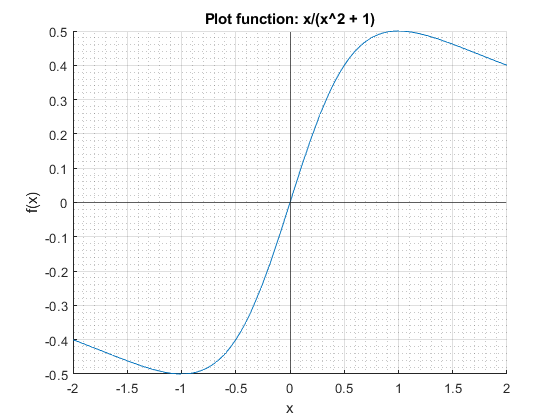

% close all
figure();
hold on;

% Define a function
syms x
f_x = (x)/(x^2 + 1);

% Set bounds on the domain
fl_x_lower = -2;
fl_x_higher = 2;

% Graph
fplot(f_x, [fl_x_lower, fl_x_higher])

% Add x-axis and y-axis
xline(0);
yline(0);

% Title and y and y-able
title(['Plot function: ' char(f_x)],'Interpreter',"none");
ylabel('f(x)');
xlabel('x');

% Add grids
grid on;
grid minor;

Plot a function that is not defined at all points along the real line. Note also that the function always returns a positive value. Note the fplot function automatically identifies the part of the x-axis where the function is not defined, and draws dashed lines to demarcate. 

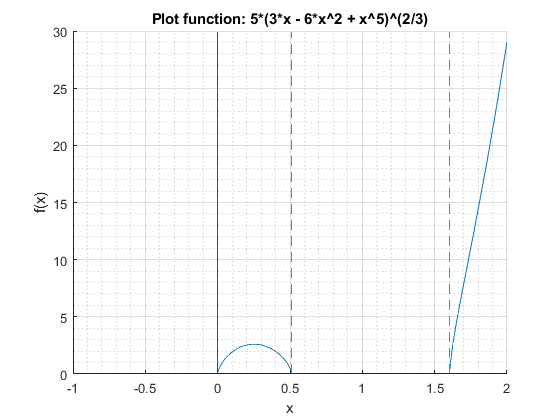

% close all
figure();
hold on;

% Define a function
syms x
f_x = 5*(x^5 - 6*x^2 + 3*x)^(2/3);

% Set bounds on the domain
fl_x_lower = -1;
fl_x_higher = 2;

% Graph
fplot(f_x, [fl_x_lower, fl_x_higher])

% Add x-axis and y-axis
xline(0);
yline(0);

% Title and y and y-able
title(['Plot function: ' char(f_x)],'Interpreter',"none");
ylabel('f(x)');
xlabel('x');

% Add grids
grid on;
grid minor;

## Plot Indifference Curve and Budget Constraint

Indifference curve and two budget lines. From [two period consumption and savings problem](https://fanwangecon.github.io/Math4Econ/derivative_application/htmlpdfm/K_save_households.html).

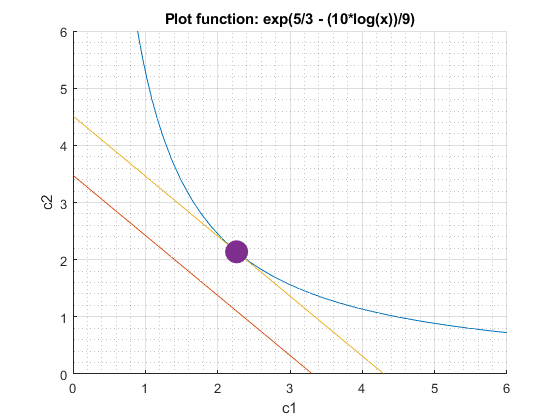

% close all
figure();
hold on;

% Define parameters
e1 = 1.5;
e2 = 1.9;
r = 0.05;

u_star = 1.5;
beta = 0.9;

% Define a function
% x = c1, f_x = c2
syms x
f_x_indiff = exp((u_star - log(x))/beta);

% Formula for optimal choice that minimize expenditure
c2_star_exp_min = exp((u_star + log(beta*(1+r)))/(1+beta));
c1_star_exp_min = (1/(beta*(1+r)))*c2_star_exp_min;
f_optimal_cost = c1_star_exp_min*(1+r)+c2_star_exp_min;

% budget equation
% x = c1, f_x = y
f_x_budget = (e1*(1+r) + e2) + (-1)*(1+r)*x;
f_x_budget_optimal_cost = f_optimal_cost + (-1)*(1+r)*x;

% Set bounds on the domain
fl_x_lower = 0;
fl_x_higher = 6;

% Graph
hold on;
fplot(f_x_indiff, [fl_x_lower, fl_x_higher])
fplot(f_x_budget, [fl_x_lower, fl_x_higher])
fplot(f_x_budget_optimal_cost, [fl_x_lower, fl_x_higher])

% plot a one point scatter plot
scatter(c1_star_exp_min, c2_star_exp_min, 300, 'filled');

% Add x-axis and y-axis
xline(0);
yline(0);

% Title and y and y-able
title(['Plot function: ' char(f_x_indiff)],'Interpreter',"none");
ylabel('c2');
xlabel('c1');

% this sets x and y visual boundaries
ylim([0,6]);
xlim([0,6]);
% Add grids
grid on;
grid minor;